clear;
load("DFD_FeaturesAll.mat");

% Time Tables are equivelant to the Signal Numbers i.e. TimeTable = 21.07
signalName = [  
                "TimeTable_sigstats/"...
                "TimeTable1_sigstats/"...
                "TimeTable2_sigstats/"...
                "TimeTable3_sigstats/"...
                "TimeTable4_sigstats/"...
                "TimeTable5_sigstats/"...
                "TimeTable6_sigstats/"...
                "TimeTable7_sigstats/"...
                "TimeTable8_sigstats/"...
                "TimeTable9_sigstats/"...
                "TimeTable10_sigstats/"...
                "TimeTable11_sigstats/"
              ];
numOfSignals = size(signalName, 2);

% Names of the signals (only needed for labels)
sensorNames = [ 
                "1. 21:07 Angle over Rolls (degrees)"...
                "2. 21:10 Position over Rolls (mm)"...
                "3. 21:12 Actual moment over Rolls (Nm)"...
                "4. 21:17 Angle under roll (degrees)"...
                "5. 21:20 Actual moment under Rolls (Nm)"... 
                "6. 21:28 Vibration measurements (mm per s)"...               
                "7. 21:31 Width position (mm)"...
                "8. 31:32 Height position (?)"...
                "9. 21:33 Error position for height (?)"...
                "10. 21:34 Error position for the width (?)"...
                "11. 21:35 Set point force (KN)"... 
                "12. 21:36 Actual force (KN)"
              ];

% Time domain features produced by Matlab DFD
featureNames = [
                "ClearanceFactor"... %1
                "CrestFactor"... %2
                "ImpulseFactor"... %3
                "Kurtosis"... %4
                "Mean"... %5
                "PeakValue"... %6
                "RMS"... %7
                "SNR"... %8
                "SINAD"... %9
                "ShapeFactor"... %10
                "Skewness"... %11
                "Std"... %12
                "THD" %13
               ];
numOfFeatures = size(featureNames, 2);

## Calculate the R2 Value for each combination of signals

warning('off','all')
correlatedSignalMatrix = cell(numOfSignals,numOfFeatures);

correlatedSignalMatrix = 12×13 cell array
    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}
    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}
    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}
    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}
    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 d

for i = 1:numOfSignals
    for j = i:numOfSignals
        str = "";
        for k = 1:numOfFeatures
            mdl = fitlm(FeaturesAll.(signalName(i) + featureNames(k)),FeaturesAll.(signalName(j)  + featureNames(k)));
            R2 = mdl.Rsquared.Ordinary;
            if R2 > 0.9 && R2 < 1
                str = str + sprintf('%i %s %3g \n', k, featureNames(k), round(R2, 3));  
                correlatedSignalMatrix{i, j} = [correlatedSignalMatrix{i, j} k];
            end
        end
        if (str ~= "")
            disp( sensorNames(i) + " " + sensorNames(j) );
            disp(str)
        end
    end
end

2. 21:10 Position over Rolls (mm) 8. 31:32 Height position (?)


5 Mean 0.995 
6 PeakValue 0.995 
7 RMS 0.995 



3. 21:12 Actual moment over Rolls (Nm) 5. 21:20 Actual moment under Rolls (Nm)


1 ClearanceFactor 0.943 
2 CrestFactor 0.946 
3 ImpulseFactor 0.944 
5 Mean 0.997 
6 PeakValue 0.995 
7 RMS 0.997 
10 ShapeFactor 0.921 
11 Skewness 0.912 
12 Std 0.977 
13 THD 0.914 



7. 21:31 Width position (mm) 10. 21:34 Error position for the width (?)


4 Kurtosis 0.928 
8 SNR 0.992 
9 SINAD 0.99 
12 Std 0.923 
13 THD 0.937 



11. 21:35 Set point force (KN) 12. 21:36 Actual force (KN)


5 Mean 0.908 
7 RMS 0.908 



## Plot signals that have R2 above threshold

Signal 2:Signal 8 - Features: 3

Num of correlated features: 3

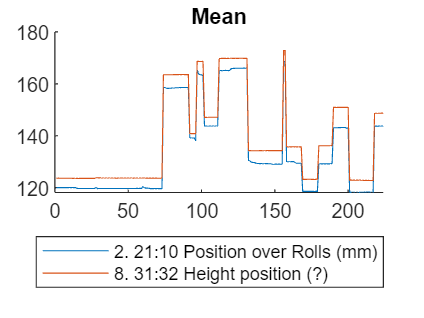

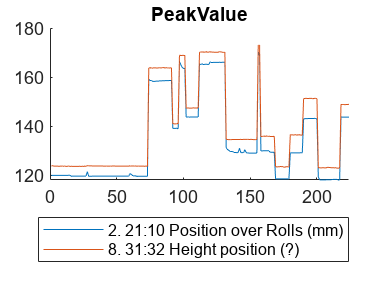

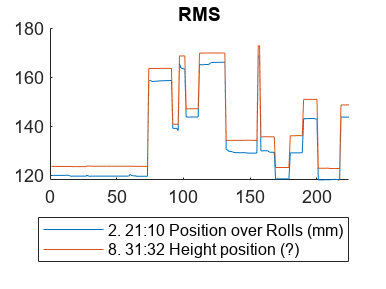

Signal 3:Signal 5 - Features: 10

Num of correlated features: 10

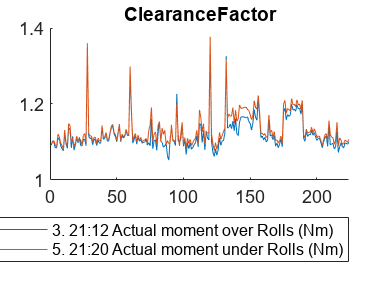

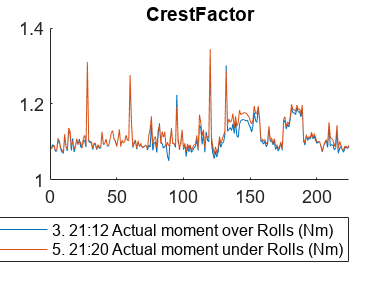

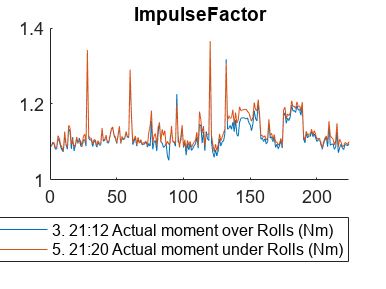

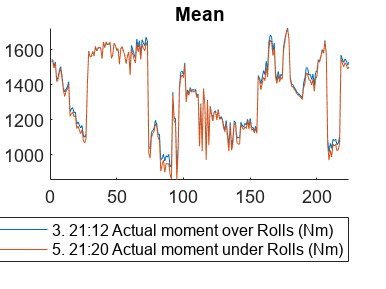

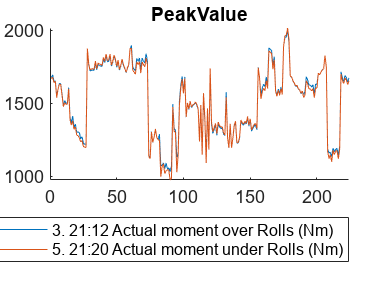

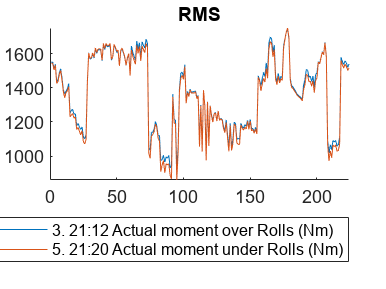

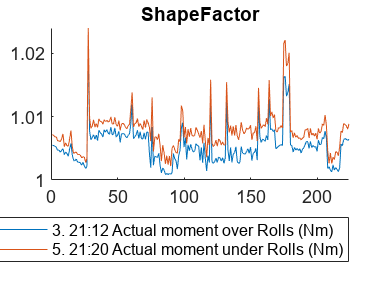

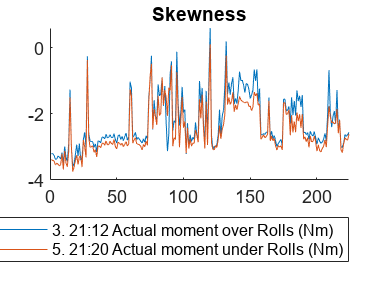

Signal 7:Signal 10 - Features: 5

Num of correlated features: 5

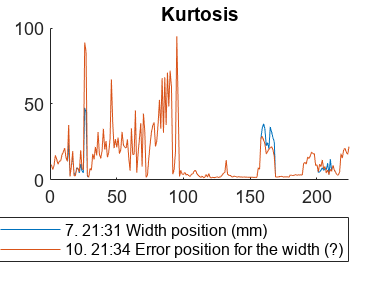

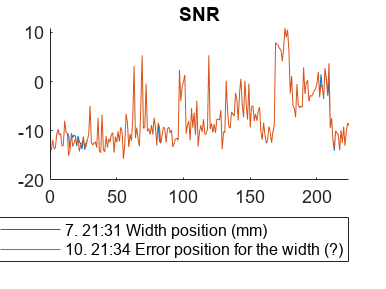

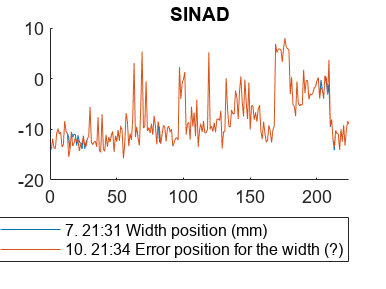

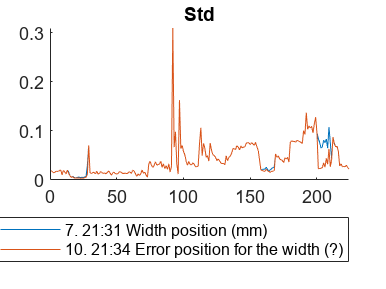

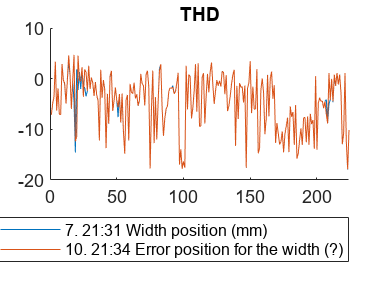

Signal 11:Signal 12 - Features: 2

Num of correlated features: 2

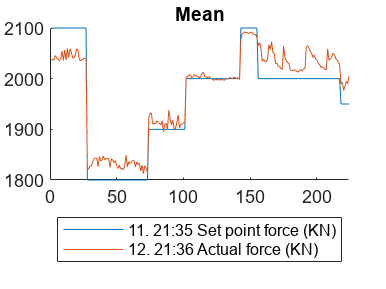

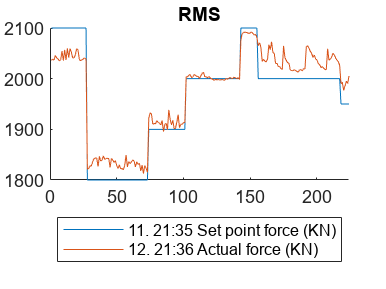

% plotCorrelatedSignals(2, 8, correlatedSignalMatrix{2,8})
% 
% plotCorrelatedSignals(3, 5, correlatedSignalMatrix{3,5})
% 
% plotCorrelatedSignals(7, 10, correlatedSignalMatrix{7,10})
% 
% plotCorrelatedSignals(11, 12, correlatedSignalMatrix{11,12})

for i=1:numOfSignals
    for j=1:numOfSignals
        if (size(correlatedSignalMatrix{i,j}, 2))
            fprintf("Signal %i:Signal %i - Features: %i", i, j, size(correlatedSignalMatrix{i,j}, 2));
            plotCorrelatedSignals(i, j, correlatedSignalMatrix{i,j}, sensorNames, featureNames, signalName, FeaturesAll)
        end;
    end;
end;

% sig1 = FeaturesAll.(signalName(j) + featureName);
% sig2 = FeaturesAll.(signalName(i-1) + featureName);
% correlation_coeff = corrcoef(sig1, sig2);
% r_sqr = power(correlation_coeff,2)

%ytrue = FeaturesAll.(signalName(12) + featureName);
%ypred = FeaturesAll.(signalName(11)  + featureName2);
%Rsq = 1 - sum((ytrue - ypred).^2)/sum((ytrue - mean(ytrue)).^2)

## Function to plot correlation features

function [] = plotCorrelatedSignals(signalNum1, signalNum2, correlatedFeatures, sensorNames, featureNames, signalName, FeaturesAll)
    fprintf("Num of correlated features: %i", length(correlatedFeatures))
    for i=1:size(correlatedFeatures, 2)
        figure(); hold on;
        feature = featureNames(correlatedFeatures(i));
        plot(FeaturesAll.(signalName(signalNum1) + feature));
        plot(FeaturesAll.(signalName(signalNum2) + feature));
        legend(sensorNames(signalNum1), sensorNames(signalNum2), "Location", 'southoutside');
        title(feature);
    end
end